# Hughe's flow Third Attempt

## Defining the Domain

Nx = 400; Ny = 200;
Lx = 100; Ly = 50;
dx = Lx/Nx; dy = Ly/Ny;
[x, y] = meshgrid(linspace(dx,Lx,Nx), linspace(dy,Ly,Ny));

## Setting the Parameters

Vmax = 1;
rho_max = 1;
CFL = 0.4;

## Initialising the Initial Condition

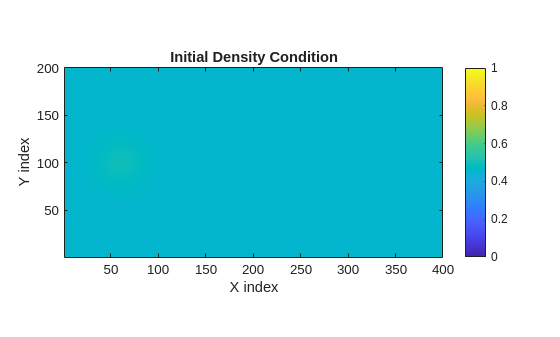

% Assigning zero density everywhere 
rho = 0.2*ones(Nx,Ny); 
% Initial density condition 
rho(10:Nx-10,10:15) = 0.65;
rho = min(rho,rho_max); 

% Gaussian blob parameters
xc = 0.25;          % center x
yc = 0.5;          % center y
sigma = 0.08;      % width of blob

% Initial condition (Gaussian blob)
rho = 0.25*exp( -((x - xc).^2 + (y - yc).^2) / (2*sigma^2) ) + 0.45;

% Initial Condition (Gaussian Blob)
xc = 15;
yc = 25;
sigma = 5;
% width
rho = 0.05*exp( -((X-xc).^2 + (Y-yc).^2) / (2*sigma^2) ) + 0.45;

% Plotting the result. 
figure; 
contourf(rho, 20, 'LineColor', 'none'); 
colorbar; axis equal tight;
clim([0 1])
xlabel('X index'); 
ylabel('Y index'); 
title('Initial Density Condition');

## The main function for time marching

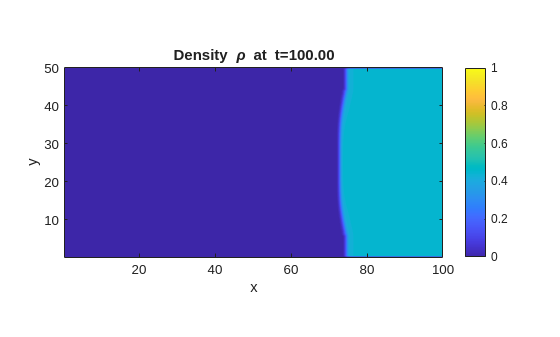

Tfinal = 100; 
t = 0; 
while t < Tfinal 
    % Speed field 
    f = Vmax*(1 - rho/rho_max); 
    % To speed doesn't become zero completely 
    f(f<1e-6) = 1e-6; 
    % Solve eikonal equation 
    phi = fast_sweeping(1./f,dy,dx,Nx,Ny); 
    % Direction field 
    [phix, phiy] = gradient(phi, dx, dy); 
    grad_mag = sqrt(phix.^2 + phiy.^2) + 1e-12; 
    dirx = -phix ./ grad_mag; 
    diry = -phiy ./ grad_mag; 
    % Velocity field 
    vx = f .* dirx;
    vy = f .* diry; 
    % Time step 
    maxspeed = max(max(sqrt(vx.^2 + vy.^2))); 
    dt = CFL * min(dx,dy) / maxspeed; 
    if t+dt > Tfinal, dt = Tfinal-t; end 
    % Update rho 
    rho = upwind_update(rho, vx, vy, dx, dy, dt,rho_max);
    % Advance time 
    t = t + dt;
    % Plots 
    if mod(round(t/dt),2) == 0 
        % Density (phi) 
        figure(1); 
        contourf(x, y, rho, 20, 'LineColor', 'none'); 
        colorbar; 
        caxis([0 rho_max]); 
        title(sprintf('Density \\rho at t=%.2f', t)); 
        xlabel('x'); ylabel('y'); 
        axis equal tight; 
        drawnow;
    end 
end

## Fast sweep Algorithm

function phi = fast_sweeping(invf, dy, dx, Nx, Ny)

    %---------------------------------------------
    % Initialization
    %---------------------------------------------
    phi = inf(Ny, Nx);
    phi(:, Nx) = 0;                 % right edge = 0

    for sweep = 1:20                

        % === Sweep 1: i→, j→  (bottom-left to top-right)
        for i = 2:Nx-1
            for j = 2:Ny-1
                phi = update_phi(phi, invf, i, j, dx);
            end
        end

        % === Sweep 2: i←, j→  (bottom-right to top-left)
        for i = Nx-1:-1:2
            for j = 2:Ny-1
                phi = update_phi(phi, invf, i, j, dx);
            end
        end

        % === Sweep 3: i←, j←  (top-right to bottom-left)
        for i = Nx-1:-1:2
            for j = Ny-1:-1:2
                phi = update_phi(phi, invf, i, j, dx);
            end
        end

        % === Sweep 4: i→, j←  (top-left to bottom-right)
        for i = 2:Nx-1
            for j = Ny-1:-1:2
                phi = update_phi(phi, invf, i, j, dx);
            end
        end

        % Boundary conditions
        phi(:, 1) = phi(:, 2);
        phi(:, Nx) = 0;
        phi(1, :) = phi(2, :);
        phi(Ny, :) = phi(Ny-1, :);
    end
end


% =========================================================
% Subfunction: update one grid point (Godunov form)
% =========================================================
function phi = update_phi(phi, invf, i, j, dx)
    a = min(phi(j, i-1), phi(j, i+1));   % x-direction neighbors
    b = min(phi(j-1, i), phi(j+1, i));   % y-direction neighbors
    f = invf(j, i);

    if abs(a - b) >= f * dx
        phi(j, i) = min(a, b) + f * dx;
    else
        inside = 2 * (f * dx)^2 - (a - b)^2;
        phi(j, i) = (a + b + sqrt(max(inside, 0))) / 2;
    end
end

## Up-winding scheme

function rho_new = upwind_update(rho, vx, vy, dx, dy, dt,rho_max) 
    [Ny, Nx] = size(rho); 
    % Boundary Condition
    for j = 2 : Ny-1
        rho(j,1) = 0;
        rho(j,Nx) = rho(j,Nx-1);
    end
    for i = 2 : Nx-1
        rho(1,i) = 0;
        rho(Ny,i) = 0;
    end
    % Initalizing the flux values to be zero intially. 
    flux_xp = zeros(Ny,Nx);
    flux_xm = zeros(Ny,Nx);
    flux_yp = zeros(Ny,Nx);
    flux_ym = zeros(Ny,Nx); 
    % Upwinding scheme implementation 
    for j = 2 : Ny-1 
        for i = 2 : Nx-1 
            % x-direction fluxes
            flux_xp(j,i) = max(vx(j,i),0)*rho(j,i)   + min(vx(j,i),0)*rho(j,i+1);
            flux_xm(j,i) = max(vx(j,i),0)*rho(j,i-1) + min(vx(j,i),0)*rho(j,i);

            % y-direction fluxes
            flux_yp(j,i) = max(vy(j,i),0)*rho(j,i)   + min(vy(j,i),0)*rho(j+1,i);
            flux_ym(j,i) = max(vy(j,i),0)*rho(j-1,i) + min(vy(j,i),0)*rho(j,i);
        end 
    end 
    % Finite difference equation obtained form discritization of continuity equation. 
    rho_new = rho - (dt/dx) * (flux_xp - flux_xm) - (dt/dy) * (flux_yp - flux_ym);
    % Ensuring density lie between the 0 and rho_max 
    rho_new = max(0, min(rho_max, rho_new));
end